# Projekt maCaPeLa - dátová analýza

Adam Puškáš, Lukáš Radoský

Neurónové siete 2019/2020

## **Úvod**

Cieľom tejto časti projektu je poskytnúť analýzu dostupnej dátovej množiny (datasetu), ktorá bola zvolená pre účely trénovania i následnej evaluácie implementovaného modelu, založeného na hlbokých neurónových sieťach. V súvislosti s vykonanou analýzou problémovej domény sme sa rozdholi zvoliť dataset [MIR-1K](https://sites.google.com/site/unvoicedsoundseparation/mir-1k), disponujúci celkovo 1000 zvukovými nahrávkami, pričom tento dataset sa na základe odporúčaní autorov existujúcich prác [1, 2] javí byť vhodným kandidátom pre tento účel.

V sekciách nižšie uvádzame jeho podrobnejší opis.

## Základné charakteristiky

Zvolený dataset možno kvantitatívne zachytiť v rámci nasledovných charakteristík:

Druhy dát:

- hudobné súbory, zachytávajúce hudobný sprievod, resp. vokály (spev) na ľavom, resp. pravom zvukovom kanáli;

- textové anotácie hudobných súborov (tónina a "farba" hudby, texty piesní a i.);

- nahrávky reči autorov, plynulo čitajúcich texty obsiahnutých piesní.

V kontexte relevantnosti pre náš projejtk sme sa v ďalšej časti analýzy zamerali práve na množinu hudobných nahrávok.

Kvantitatívne údaje (hudobné nahrávky):

- formát nahrávok: .wav

- počet nahrávok: 1000

- zastúpenie spevákov (mužov)**: 59%

- zastúpenie speváčok (žien)**: 41%

- celková dĺžka nahrávok* [min]: 133

- celková veľkosť datasetu nahrávok [MB]: 488

- dĺžka najkratšej nahrávky* [sek]: 4

- dĺžka najdlhšej nahrávky* [sek]: 13

- chýbajúce (poškodené) dáta: žiadne

- vzorkovacia frekvencia nahrávok [Hz]:

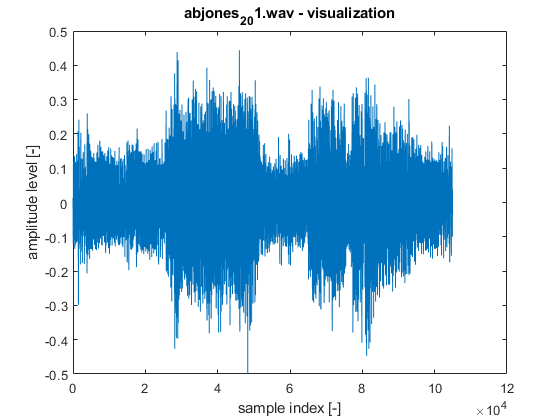

disp(importdata('MIR-1K\Wavfile_mono\abjones_2_01.wav').fs)

*  údaje dostupné na stránke datasetu

**  získané inšpekciou podľa názvu nahrávky, resp. subjektívneho vyhodnotenia na základe tónu hlasu

V rámci nasledovnej sekcie poskytujeme nasledovné vizualizácie vybranej nahrávky:

- základnú vizualizáciu jej priebehu;

- vizualizáciu spektra po FFT (pre vybrané okienko dĺžky 1024 vzoriek) - spektrogram.

Vizualizácie vybranej nahrávky ("abjones_2_01.wav"):

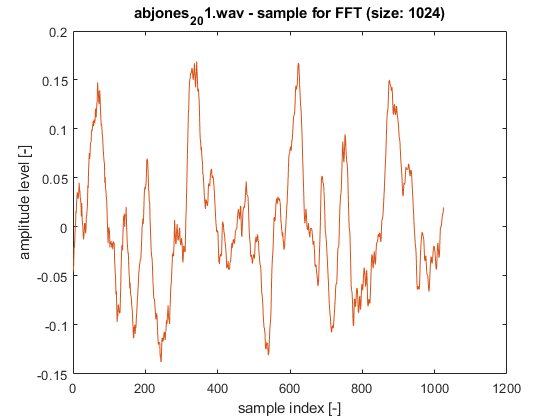

data = importdata('MIR-1K\Wavfile_mono\abjones_2_01.wav');
sample_rate = data.fs;
sample_size = 1024;

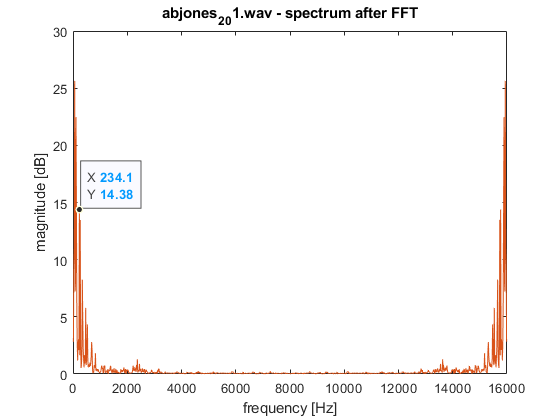

signal = data.data(:, 1); % just one channel (mixed mono)
plot(signal) % recording visualization
xlabel('sample index [-]')
ylabel('amplitude level [-]')
title('abjones_2_01.wav - visualization')

sample = signal(sample_rate: (sample_rate + sample_size));
plot(sample) % recording visualization
xlabel('sample index [-]')
ylabel('amplitude level [-]')
title('abjones_2_01.wav - sample for FFT (size: 1024)')

FFT = fft(sample); % FFT computation

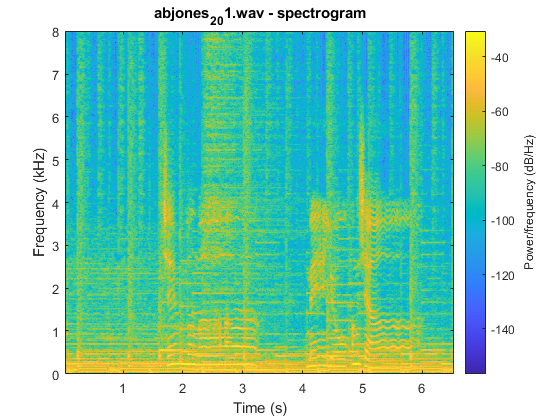


% spectral coefficient transformation (for spectrogram vis.)
freq_fig = 0:(sample_rate/(length(sample))):sample_rate-1;

plot(freq_fig, abs(FFT)) % spectrum visualization
xlabel('frequency [Hz]')
ylabel('magnitude [dB]')
title('abjones_2_01.wav - spectrum after FFT')

ax2 = gca; % auxiliary
chart2 = ax2.Children(448);
datatip(chart2,234.1,13.87);

spectrogram(signal, sample_size, 1000, sample_size, sample_rate, 'yaxis')
title('abjones_2_01.wav - spectrogram')

## **Možné úskalia a zhodnotenie**

V rámci tejto časti zadania sme sa bližšie pozreli na dataset MIR-1K, ktorý sme sa rozhodli použiť v kontexte nášho projektu, ktorého cieľom je natrénovať model na báze neurónových sietí pre účely separovania vokálov od hudobného sprievodu v nahrávkach, obsahujúcich oboje. Vzhľadom na vysokú kvalitu datasetu (žiadne chýbajúce, resp. poškodené dáta) a jeho dobrú štruktúru nepredpokladáme výrazné komplikácie v súvislosti s jeho použitím. Za jediné potenciálne úskalie možno označiť skutočnosť, že nahrávky nemajú konzistentnú dĺžku - z tohto dôvodu bude potrebné ich ďalšie predspracovanie, napríklad vo forme ich spojenia do väčších celkov, s potenciálnym zarovnaním technikou doplnenia nulami (tzv. *zero padding*).

## Bibliografia

[1] CHANDNA, P. et al. Monoaural Audio Source Separation Using Deep Convolutional Neural Networks. In: *International Conference on Latent Variable Analysis and Signal Separation* [online]. Barcelona: Universitat Pompeu Fabra, 2017. Dostupné na internete: http://mtg.upf.edu/node/3680

[2] HUANG, P. et al. Singing-voice Separation from monaural recordings. In: *International Society for Music Information Retrieval Conference (ISMIR)* [online]. Illinois: University of Illinois, 2014. Dostupné na internete: https://posenhuang.github.io/papers/DRNN_ISMIR2014.pdf

       16000

